clc
clear variables
close all

**Parameters for Hub, Vsat, Satellite Combination**

Hub in Kuala Lumpur

HubLat = 3.1390;
HubLong = 101.6869;
HubGoverT = 30; % G/T in dB/K Calculation of Gain of transmitting antenna based on diameter of antenna

Vsat in Sabah

VsatLat = 5.9788;
VsatLong = 116.0753;
VsatGoverT = 15; % G/T in dB/K Calculation of Gain of transmitting antenna based on diameter of antenna
P = 16; % Transmit Power in W
Pdb = 10*log10(P); % Transmit Power in dBW
G = 39; % Gain in dBi
VsatEIRP = Pdb + G; % EIRP in dB
SFD = -88; % Saturation Flux Density in dBW/m^2

Geostationary Satellite

SatLat = 0;
SatLong = 90;
SatAlt = 35786; % Altitude in KMs
f = 12; % Frequency in GHz
SatEIRP = 57; % Saturated EIRP in dBW
SatGoverT = 14.56; % G/T in dB/K
TBW = 36; % Transponder Bandwith in MHz
AtmosLoss = 0.4; % Atmospheric Loss in dB
BoltzmanConstant = -228.6;
CBW = 1.2; % Channel Bandwith in MHz
FR = 0.2; % Channel Bandwith Filter Rolloff in %
FilteredCBW = CBW * (1-FR);
CosineRolloff = 1.2;
%PeakTGain = 33.5; % Peak Transmit Gain in dB

Earth

Re = 6378; % Earth Radius in KMs
Rs = SatAlt + Re; % Satellite Radius in KMs

## **Part 1: Look Up Angles / Elevation and Slant Range and Free Space Loss**

HubGamma = gamma(SatLat,SatLong,HubLat,HubLong);
HubVisT = visibilitytest(HubGamma,Re,Rs);
if HubVisT == 1
    HubElevation = elevation(HubGamma,Re,Rs);
    [HubAlpha,HubAzimuth] = azimuth(SatLat,SatLong,HubLat,HubLong,HubGamma);
    SatelliteHubSlantRange = slantrange(Re,Rs,HubElevation);
    HubtoSatFSPL = fspl(SatelliteHubSlantRange,f);
    
    disp('---------------Hub calculations---------------')
    disp('The elevation angle is visible (The Hub has a direct line of sight to the satellite)')
    disp(['The elevation angle or look up angle is ', num2str(round(HubElevation,1)), ' degrees'])
    disp(['The azimuth angle is ', num2str(round(HubAzimuth,1)), ' degrees'])
    disp(['The slant range is ', num2str(round(SatelliteHubSlantRange,1)), ' KMs'])
    disp(['The free space loss is ', num2str(round(HubtoSatFSPL,1)), ' dB'])
    disp('-----------------------------------------------')
else
    disp('The Hub elevation angle is not visible so calculation is not possible (The Hub does not have a direct line of sight to the satellite)')
end

---------------Hub calculations---------------


The elevation angle is visible (The Hub has a direct line of sight to the satellite)


The elevation angle or look up angle is 75.8 degrees


The azimuth angle is 255.2 degrees


The slant range is 41708.3 KMs


The free space loss is 206.4 dB


-----------------------------------------------


VsatGamma = gamma(SatLat,SatLong,VsatLat,VsatLong);
VsatVisT = visibilitytest(VsatGamma,Re,Rs);
if VsatVisT == 1
    VsatElevation = elevation(VsatGamma,Re,Rs);
    [VsatAlpha,VsatAzimuth] = azimuth(SatLat,SatLong,VsatLat,VsatLong,VsatGamma);
    SatelliteVsatSlantRange = slantrange(Re,Rs,VsatElevation);
    VsattoSatFSPL = fspl(SatelliteVsatSlantRange,f);
    
    disp('---------------Vsat calculations---------------')
    disp('The elevation angle is visible (The Vsat has a direct line of sight to the satellite)')
    disp(['The elevation angle or look up angle is ', num2str(round(VsatElevation,1)), ' degrees'])
    disp(['The azimuth angle is ', num2str(round(VsatAzimuth,1)), ' degrees'])
    disp(['The slant range is ', num2str(round(SatelliteVsatSlantRange,1)), ' KMs'])
    disp(['The free space loss is ', num2str(round(VsattoSatFSPL,1)), ' dB'])
    disp('-----------------------------------------------')
else
    disp('The Vsat elevation angle is not visible so calculation is not possible (The Vsat does not have a direct line of sight to the satellite)')
end

---------------Vsat calculations---------------


The elevation angle is visible (The Vsat has a direct line of sight to the satellite)


The elevation angle or look up angle is 58.8 degrees


The azimuth angle is 258 degrees


The slant range is 41809.5 KMs


The free space loss is 206.5 dB


-----------------------------------------------


## Part 2: FWD Link (HUB TO SATELLITE TO TERMINAL)

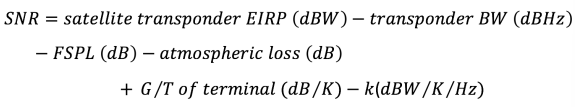

if HubVisT == 1 && VsatVisT == 1
    FWDSNR = SatEIRP - 10*log10(TBW * 10.^6) - HubtoSatFSPL - AtmosLoss + VsatGoverT - (BoltzmanConstant);
    disp(['The FWD link SNR is ', num2str(round(FWDSNR,1)), ' dB'])
end

The FWD link SNR is 18.2 dB


## Part 3: Simple RTN Link (TERMINAL TO SATELLITE)

%GainatAngle = PeakTGain + CosineRolloff*10*log10(cosd(HubElevation)); % In dB   

if VsatVisT == 1
    sRTNSNR = Pdb + G - 10*log10(FilteredCBW * 10.^6) - VsattoSatFSPL - AtmosLoss + SatGoverT - (BoltzmanConstant);
    disp(['The Simple RTN link SNR is ', num2str(round(sRTNSNR,1)), ' dB'])
end

The Simple RTN link SNR is 27.5 dB


## **Part 4: Complex RTN Link (TERMINAL TO SATELLITE TO HUB)**

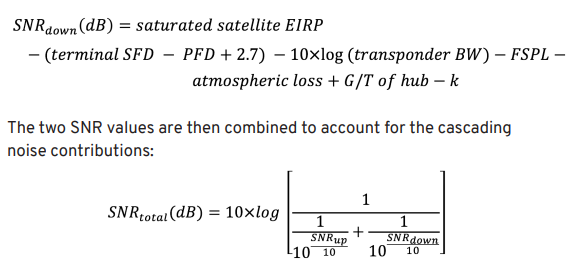

if HubVisT == 1 && VsatVisT == 1
    PFD = VsatEIRP - 20*log10(SatelliteVsatSlantRange*10.^3) - 10*log10(4*pi); % Power Flux Density in dBW/m^2
    VsatSFD = SFD - 10*log10(TBW/FilteredCBW); % Saturation Flux Density in dBW/m^2
    sRTNSNR2 = SatEIRP - (VsatSFD - PFD + 2.7) - 10*log10(TBW * 10.^6) - HubtoSatFSPL - AtmosLoss + HubGoverT - (BoltzmanConstant);
    RTNSNR = 10*log10(1/((1/10.^(sRTNSNR/10))+(1/10.^(sRTNSNR2/10))));
    disp(['The Complex RTN link SNR is ', num2str(round(RTNSNR,1)), ' dB'])
end

The Complex RTN link SNR is 20.8 dB


**Calculation of Gamma**

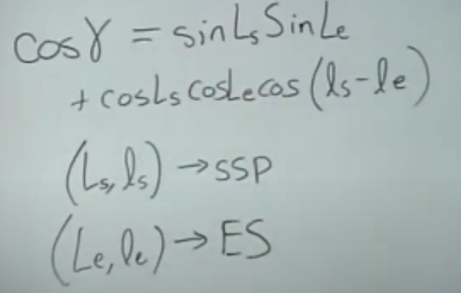

function gam = gamma(SatLat,SatLong,EarthLat,EarthLong)
    a = sind(SatLat)*sind(EarthLat);
    b = cosd(SatLat)*cosd(EarthLat)*cosd(SatLong-EarthLong);
    gam = acosd(a+b);
end

**Visibility Test**

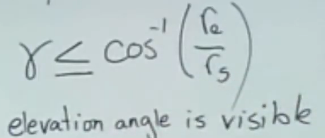

function VisT = visibilitytest(gamma,re,rs)
    a = acosd(re/rs);
    if gamma <= a
        VisT = true;
    else
        VisT = false;
    end
end

**Calculation of Elevation**

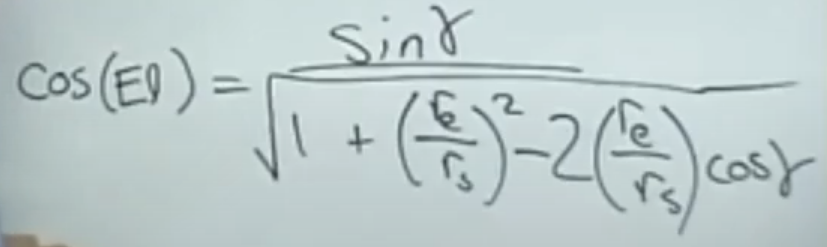

function elv = elevation(gamma,re,rs)
    a = sind(gamma);
    b = sqrt(1+(re/rs).^2-(2*(re/rs)*cosd(gamma)));
    elv = acosd(a/b);
end

**Calculation of Azimuth**

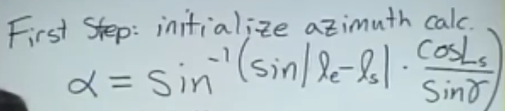

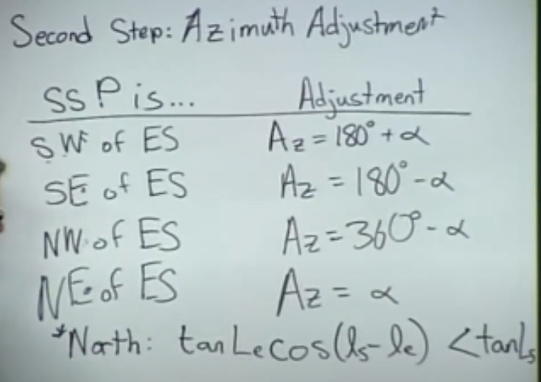

function [alpha,az] = azimuth(SatLat,SatLong,EarthLat,EarthLong,gamma)
    a = sind(abs(EarthLong-SatLong))*(cosd(SatLat)/sind(gamma));
    alpha = asind(a);
    b = tand(EarthLat)*cosd(SatLong-EarthLong);
    c = tand(SatLat);
    if b > c && SatLong > EarthLong
        az = 180 - alpha;
    elseif b < c && SatLong < EarthLong
        az = 360 - alpha;
    elseif b > c && SatLong < EarthLong
        az = 180 + alpha;
    else
        az = alpha;
    end
end

**Calculation of Slant Range**

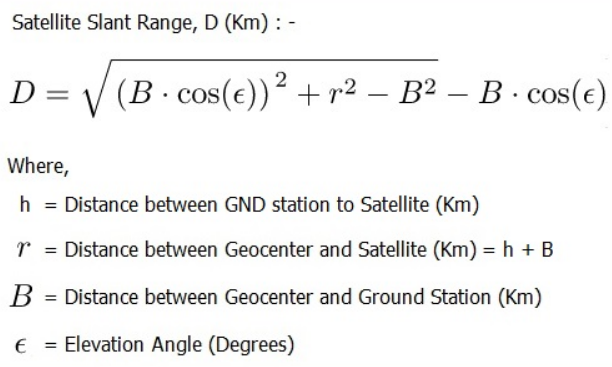

function sr = slantrange(re,rs,elevation)
    a = (re*cosd(elevation)).^2 + rs.^2;
    b = -re.^2 - re*cosd(elevation);
    sr = sqrt(a+b);
end

**Calculation of Free Space Path Loss**

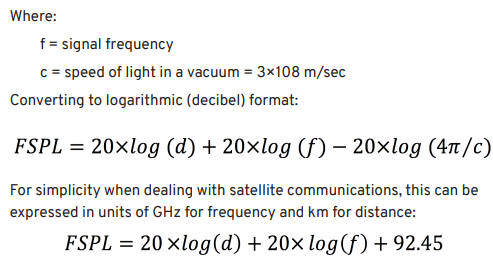

function fsl = fspl(slantrange,f)
    fsl = 20*log10(slantrange) + 20*log10(f) + 92.45;
end

**References**

[https://www.youtube.com/watch?v=bH37AwqPpdk&ab_channel=GregDurgin](https://www.youtube.com/watch?v=bH37AwqPpdk&ab_channel=GregDurgin) (Look up angles and elevation)

[https://www.rfwireless-world.com/calculators/satellite-slant-range-calculator.html](https://www.rfwireless-world.com/calculators/satellite-slant-range-calculator.html) (Slant Angle)

[https://www.kymetacorp.com/wp-content/uploads/2020/09/Link-Budget-Calculations-2.pdf](https://www.kymetacorp.com/wp-content/uploads/2020/09/Link-Budget-Calculations-2.pdf) (FSPL and Link Budget)